## TASK 1


$$Fg - F_{drag} = ma$$


Preuredimo prvo enačbo.

- 
$$mg - kv^2 = m \frac{dv}{dt}$$


- 
$$\frac{dv}{dt} = g - \frac{kv^2}{m}$$


syms v(t) g m k
DE = diff(v,t) == g - (k/m)*v;

**Pogoj**: ob t=0 je hitrost v=0

cond = v(0) == 0;

S pomočjo  `dsolve` funkcije, ki vzame diferencialno enačbo in jo reši, če dodamo še pogoj `cond`, reši enačbo glede na ta pogoj.

### 1. Hitrost

v(t) = dsolve(DE, cond)

$$v(t) = \frac{g\,m-g\,m\,{\mathrm{e}}^{-\frac{k\,t}{m}}}{k}$$

V = matlabFunction(v)

V = function_handle with value:
    @(t,g,k,m)(g.*m-g.*m.*exp(-(k.*t)./m))./k


### 2. Pospeševanje

Odvod funkcije hitrosti.

a = diff(v, t)

$$a(t) = g\,{\mathrm{e}}^{-\frac{k\,t}{m}}$$

### 3. Premik

Integral funkcije hitrosti (odvod premika => hitrost).

x = int(v, t)

$$x(t) = \frac{g\,m\,\left(m\,{\mathrm{e}}^{-\frac{k\,t}{m}}+k\,t\right)}{k^{2}}$$

Inicializiramo konstante za gravitacijo in $k$.

g = 10;
k = 1;

Naredimo 3 grafe za mase $1,2,5$ in $10$.

### Hitrost v odvisnosti od časa

figure

for mass = [1, 2, 5, 10]
    fplot(V(t, g, k, mass), [0, 60]) % za 60s
    hold on
end

m1=1, m2=2, m5=5, m10=10;

m1 = 1

m2 = 2

m5 = 5

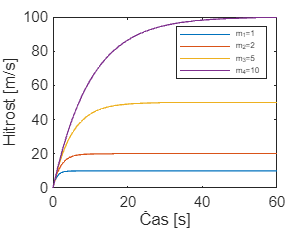

legend('m_1=1', 'm_2=2', 'm_3=5', 'm_4=10', 'FontSize', 5);
ylabel('Hitrost [m/s]');
xlabel('Čas [s]');

### Pospešek v odvisnosti od časa